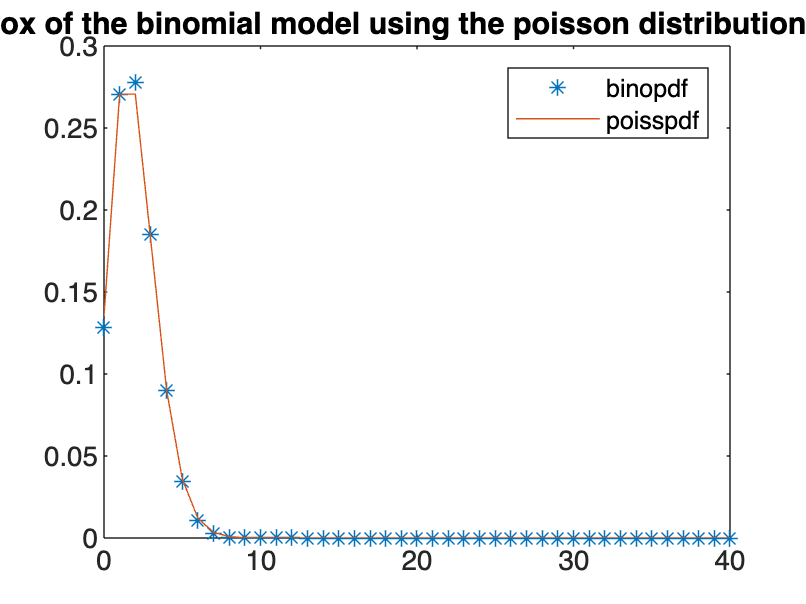

clc;
clear all;
p=input("prob of succes (p<=0.05)=");
for n=30:40
    mu=n*p;
    k=0:n;
    px=binopdf(k,n,p);
    poisspx=poisspdf(k,mu);
    plot(k,px,'*');
    hold on;
    plot(k,poisspx);
    hold off;
    title("Approx of the binomial model using the poisson distribution model")
    legend("binopdf","poisspdf");
    pause(0.5);
end